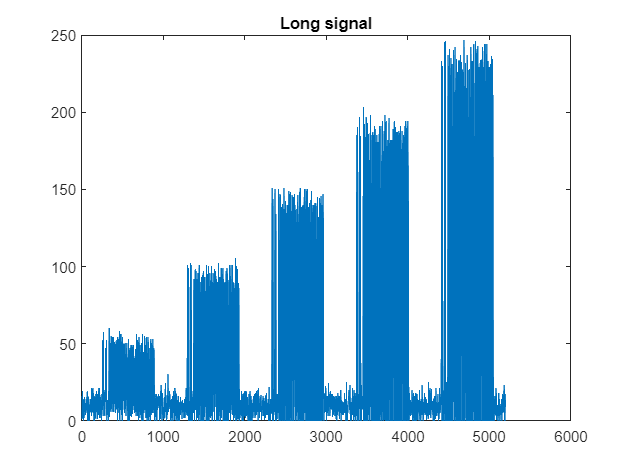

clear
load("tempNeigiamasRodiklisData.mat")

minAmplitude = 0.2;
maxAmplitude = 1.1;
stepCount = 5;

data_binary = [1 0 0 0 1 1 0 1 0 1 0 0 0 0 0 0 0 1 1 0 1 0 1 0 1 0 0 1 1 1 1 0]';
packet_bits = GenerateBits(data_binary);
singleSigLength = 1040;
ADCsignalLong = zeros(1, stepCount*singleSigLength);
idealSignalLong = zeros(1, stepCount*singleSigLength);
for generuojama_amplitude_index = 1:stepCount
    generatedAmplitude = minAmplitude + (maxAmplitude - minAmplitude)/(stepCount-1) * (generuojama_amplitude_index-1);
    [idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule] = GenerateSignal(packet_bits, generatedAmplitude);
    copyIndexStart = singleSigLength*(generuojama_amplitude_index-1)+1;
    copyIndexLast = singleSigLength*(generuojama_amplitude_index);
    ADCsignalLong(copyIndexStart:copyIndexLast) = ADCsignal;
    idealSignalLong(copyIndexStart:copyIndexLast) = idealSignal(1:10:length(idealSignal));
end
plot(ADCsignalLong)
title("Long signal")

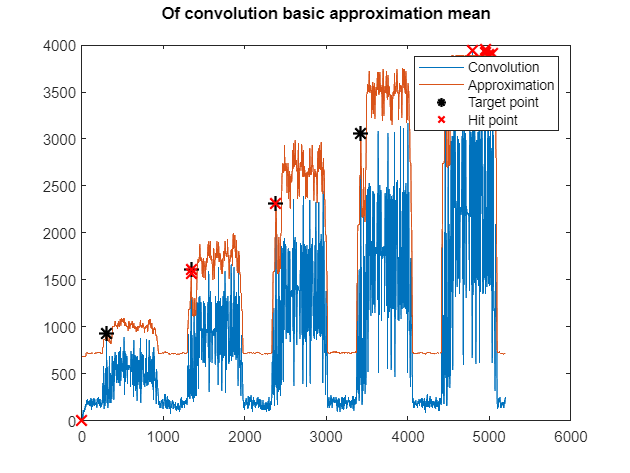

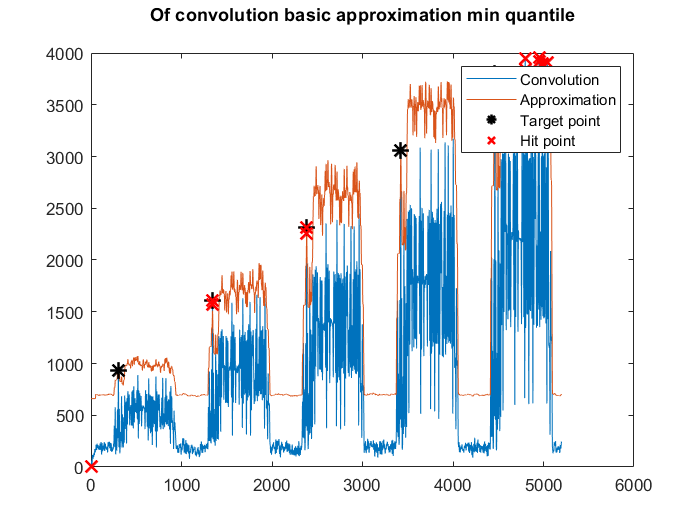

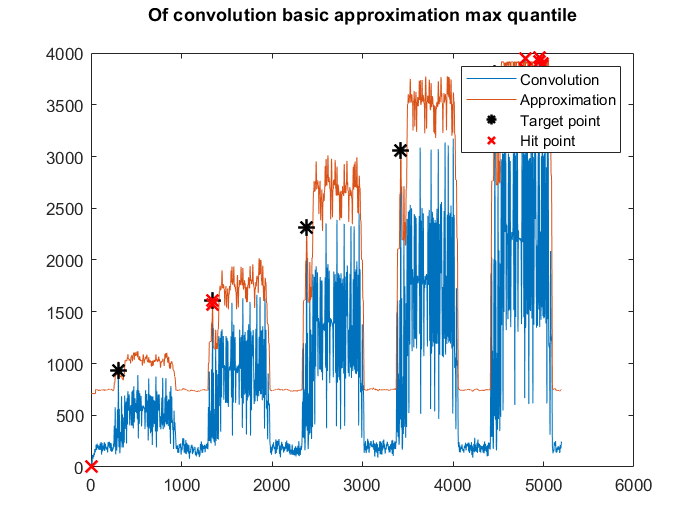

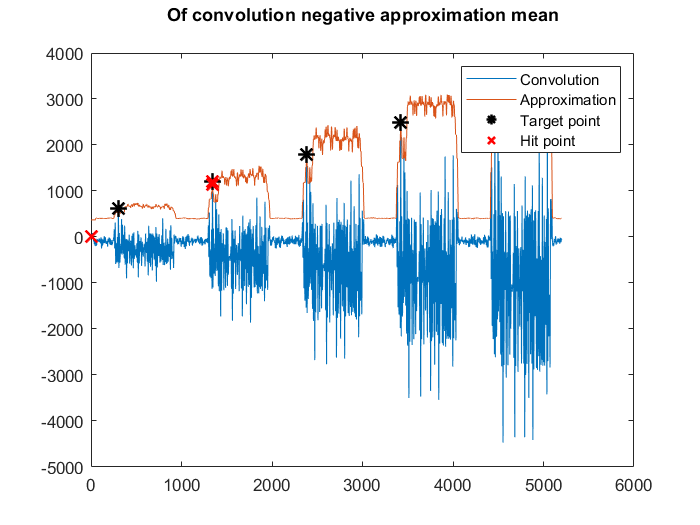

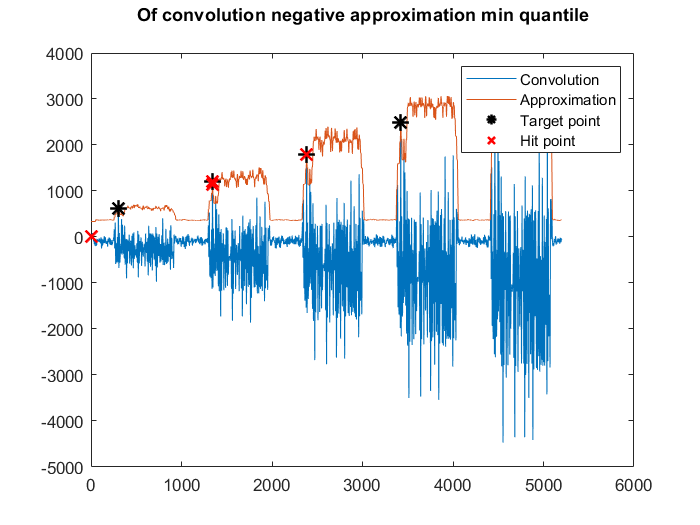

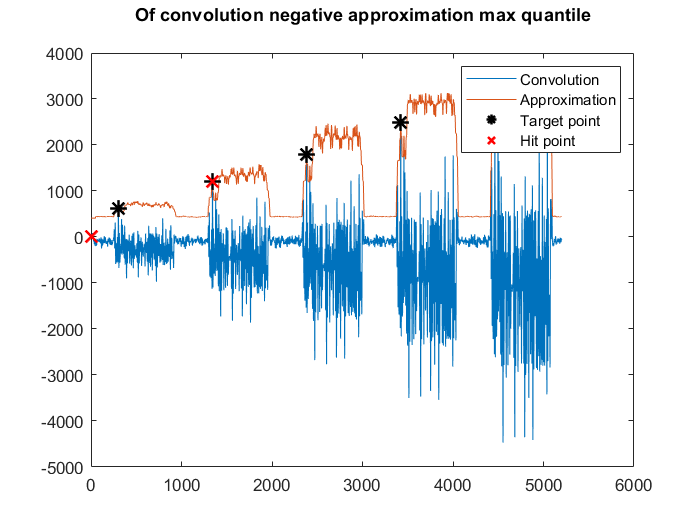

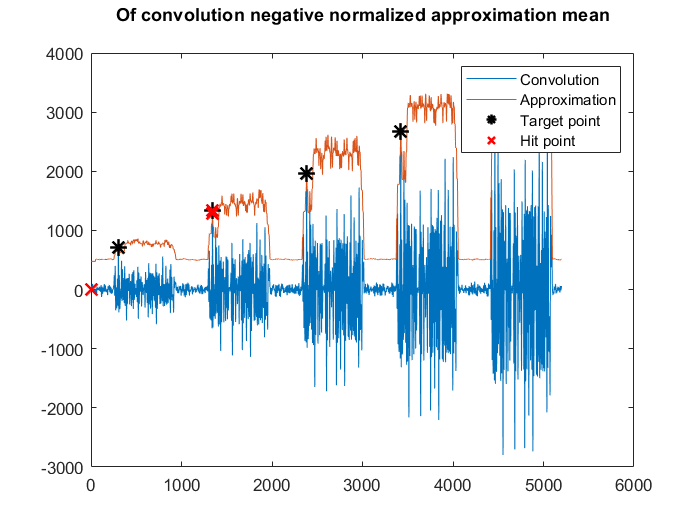

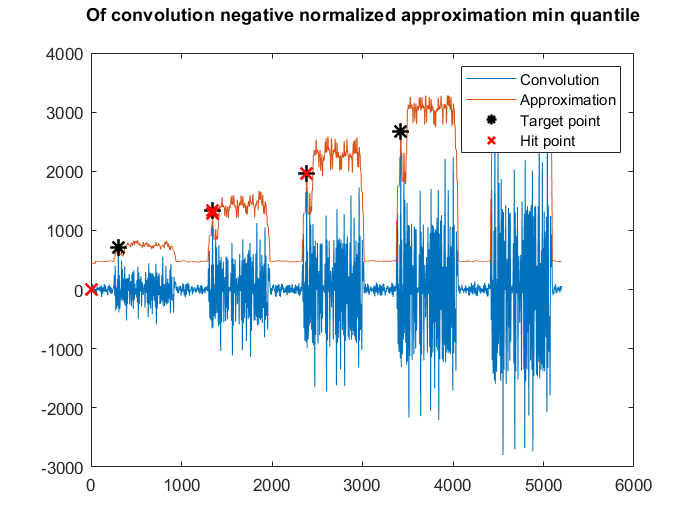

allMinimumEnergy = zeros(1, length(allApproximations));

%allMinimumEnergy((ConvolutionEnum.extendedNormalized-1) * ApproximationEnum.last + ApproximationEnum.minQuantile) = 100000;

for convIndex = 1:uint32(ConvolutionEnum.last)
    for approxIndex = 1:uint32(ApproximationEnum.last)
        approximationIndex = (convIndex-1) * uint32(ApproximationEnum.last) + approxIndex;
        if convTypes(convIndex).diffAmount == 0
            currentConvolution = GenerateConv(ADCsignalLong, convTypes(convIndex).convPreambule);
        else %Is differentiated
            movedADCsignalLong = [zeros(1, convTypes(convIndex).diffAmount), ADCsignalLong];
            diffADCsignalLong = ADCsignalLong - movedADCsignalLong(1:length(ADCsignalLong));
            currentConvolution = GenerateConv(diffADCsignalLong, convTypes(convIndex).convPreambule);
        end
        
        coeficientAmount = length(allApproximations(approximationIndex).coeficients);
        
        currentEnergy = GenerateEnergy(ADCsignalLong, length(convTypes(convIndex).convPreambule));
        %Apply energy floor
        for i = 1:length(currentEnergy)
            if(currentEnergy(i) <= allMinimumEnergy(approximationIndex))
                currentEnergy(i) = allMinimumEnergy(approximationIndex);
            end
        end
        currentApproximation =  GenerateApprox(currentEnergy, allApproximations(approximationIndex));
        
        hitPointsX = zeros(1, length(ADCsignalLong));
        hitPointsY = zeros(1, length(ADCsignalLong));
        hitPointsIndex = 1;
        for ii = 100:length(ADCsignalLong)
            if currentConvolution(ii) > currentApproximation(ii)
                hitPointsX(hitPointsIndex) = ii;
                hitPointsY(hitPointsIndex) = currentConvolution(ii);
                hitPointsIndex = hitPointsIndex + 1;
            end
        end
        hitPointsX = hitPointsX(1:hitPointsIndex);
        hitPointsY = hitPointsY(1:hitPointsIndex);
        targetPointsX = zeros(1, stepCount);
        targetPointsY = zeros(1, stepCount);
        for ii = 1:stepCount
            targetPointsX(ii) = convTypes(convIndex).expectedMaximum + length(ADCsignal) * (ii-1);
            targetPointsY(ii) = currentConvolution(targetPointsX(ii));
        end

        figure
        plot(currentConvolution, 'DisplayName', "Convolution")
        hold on
        %plot(currentEnergy, 'DisplayName', "Energy")
        plot(currentApproximation, 'DisplayName', "Approximation")
        scatter(targetPointsX, targetPointsY,100,"*", "black",'LineWidth', 1.5, 'DisplayName', "Target point")
        scatter(hitPointsX, hitPointsY,100,"x", "red",'LineWidth', 1.5, 'DisplayName', "Hit point")
        hold off
        title(sprintf("Of convolution %s approximation %s\n", convTypes(convIndex).name, allApproximations(approximationIndex).name));
        legend
    end
end

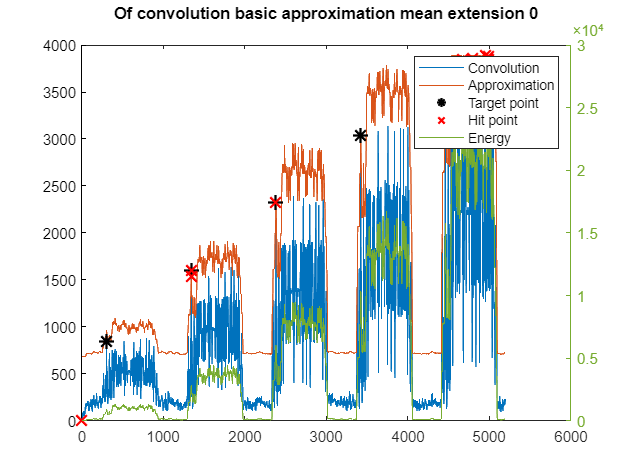

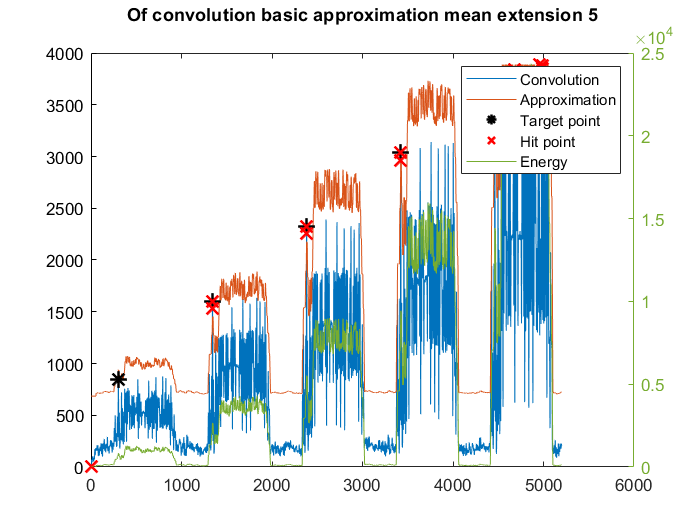

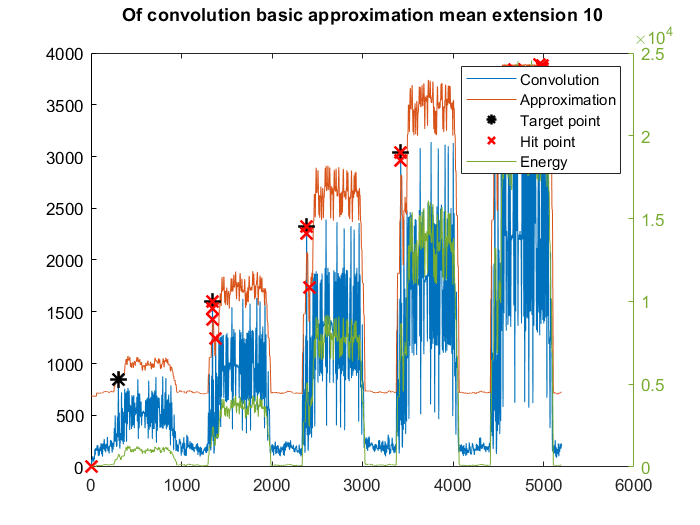

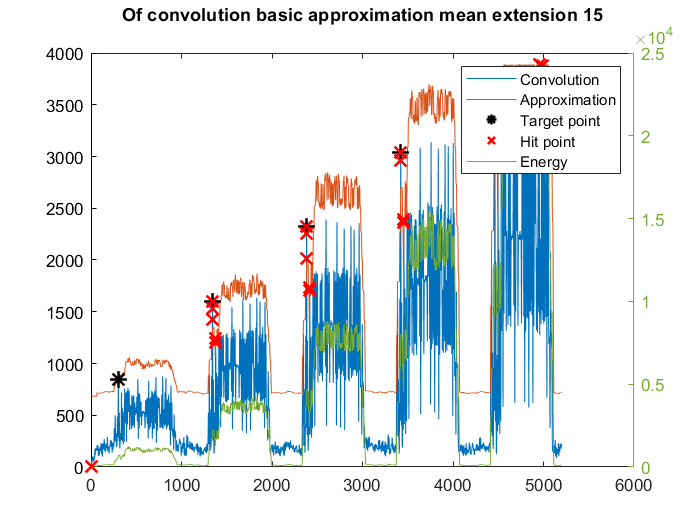

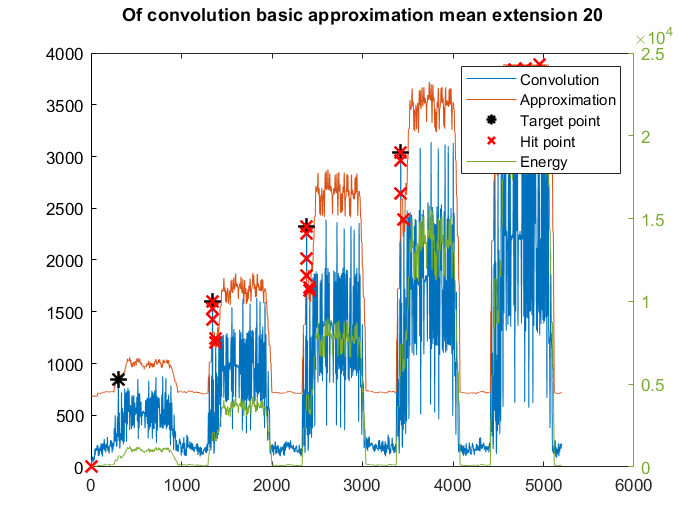

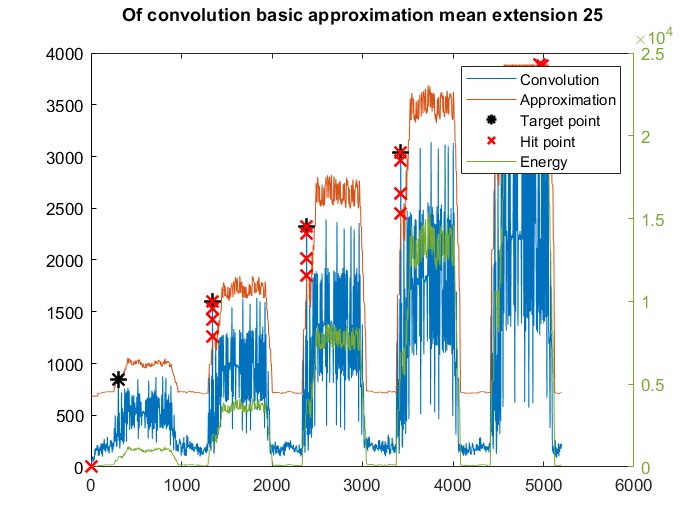

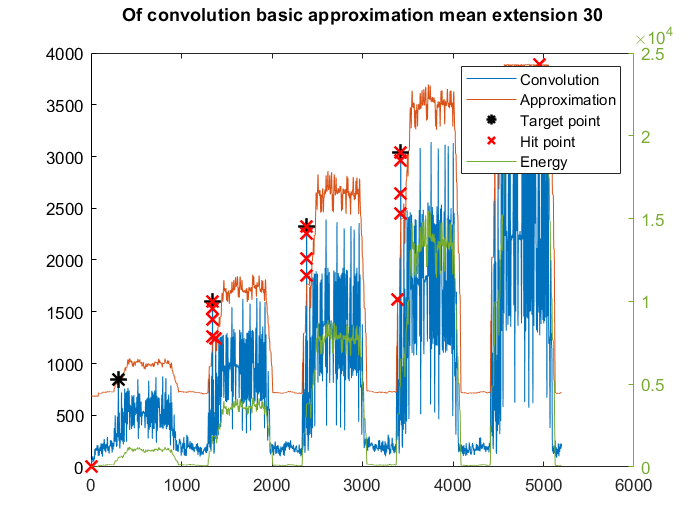

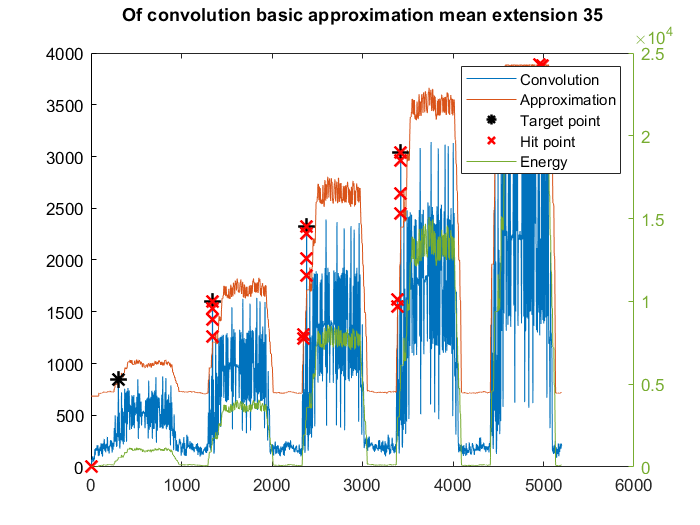

approximationIndex = 1;
convIndex = 1;

allMinimumEnergy = zeros(1, length(allApproximations));
allMinimumEnergy((ConvolutionEnum.extendedNormalized-1) * ApproximationEnum.last + ApproximationEnum.minQuantile) = 100000;

for extension = 0:5:50
    new_length = length(convTypes(convIndex).convPreambule) + extension;
    if convTypes(convIndex).diffAmount == 0
        currentConvolution = GenerateConv(ADCsignalLong, convTypes(convIndex).convPreambule);
    else %Is differentiated
        movedADCsignalLong = [zeros(1, convTypes(convIndex).diffAmount), ADCsignalLong];
        diffADCsignalLong = ADCsignalLong - movedADCsignalLong(1:length(ADCsignalLong));
        currentConvolution = GenerateConv(diffADCsignalLong, convTypes(convIndex).convPreambule);
    end
    
    coeficientAmount = length(allApproximations(approximationIndex).coeficients);
    
    currentEnergy = GenerateEnergy(ADCsignalLong, new_length);
    %Apply energy floor
    for i = 1:length(currentEnergy)
        if(currentEnergy(i) <= allMinimumEnergy(approximationIndex))
            currentEnergy(i) = allMinimumEnergy(approximationIndex);
        end
    end
    currentApproximation =  GenerateApprox(currentEnergy, allApproximations(approximationIndex));
    
    hitPointsX = zeros(1, length(ADCsignalLong));
    hitPointsY = zeros(1, length(ADCsignalLong));
    hitPointsIndex = 1;
    for ii = 100:length(ADCsignalLong)
        if currentConvolution(ii) > currentApproximation(ii)
            hitPointsX(hitPointsIndex) = ii;
            hitPointsY(hitPointsIndex) = currentConvolution(ii);
            hitPointsIndex = hitPointsIndex + 1;
        end
    end
    hitPointsX = hitPointsX(1:hitPointsIndex);
    hitPointsY = hitPointsY(1:hitPointsIndex);
    targetPointsX = zeros(1, stepCount);
    targetPointsY = zeros(1, stepCount);
    for ii = 1:stepCount
        targetPointsX(ii) = convTypes(convIndex).expectedMaximum + length(ADCsignal) * (ii-1);
        targetPointsY(ii) = currentConvolution(targetPointsX(ii));
    end

    figure
    plot(currentConvolution, 'DisplayName', "Convolution")
    hold on
    
    plot(currentApproximation, 'DisplayName', "Approximation")
    scatter(targetPointsX, targetPointsY,100,"*", "black",'LineWidth', 1.5, 'DisplayName', "Target point")
    scatter(hitPointsX, hitPointsY,100,"x", "red",'LineWidth', 1.5, 'DisplayName', "Hit point")
    yyaxis right;
    plot(currentEnergy, 'DisplayName', "Energy")
    hold off
    title(sprintf("Of convolution %s approximation %s extension %s\n", convTypes(convIndex).name, ...
          allApproximations(approximationIndex).name, num2str(extension)));
    legend
end


clear
load("tempNeigiamasRodiklisData.mat")

testAmount = 10;
minAmplitude = 0.2;
maxAmplitude = 1.1;
stepCount = 5;

data_binary = [1 0 0 0 1 1 0 1 0 1 0 0 0 0 0 0 0 1 1 0 1 0 1 0 1 0 0 1 1 1 1 0]';
packet_bits = GenerateBits(data_binary);
singleSigLength = 1040;
ADCsignalLong = zeros(1, stepCount*singleSigLength);
idealSignalLong = zeros(1, stepCount*singleSigLength);

testHitsCorrect = zeros(stepCount, length(allApproximations));
testHitsFailed = zeros(stepCount, length(allApproximations));
testAllHits = zeros(length(allApproximations), singleSigLength * stepCount);
testAllHitsAmplitude = zeros(length(allApproximations), singleSigLength * stepCount, testAmount);
testAllHitsEnergy = zeros(length(allApproximations), singleSigLength * stepCount, testAmount);

for testIndex = 1:testAmount
    for generuojama_amplitude_index = 1:stepCount
        generatedAmplitude = minAmplitude + (maxAmplitude - minAmplitude)/(stepCount-1) * (generuojama_amplitude_index-1);
        [idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule] = GenerateSignal(packet_bits, generatedAmplitude);
        copyIndexStart = singleSigLength*(generuojama_amplitude_index-1)+1;
        copyIndexLast = singleSigLength*(generuojama_amplitude_index);
        ADCsignalLong(copyIndexStart:copyIndexLast) = ADCsignal;
        idealSignalLong(copyIndexStart:copyIndexLast) = idealSignal(1:10:length(idealSignal));
    end
    for convIndex = 1:uint32(ConvolutionEnum.last)
        %Calculate target conv points, allow slight deviation
        deviation = 0; % +-1
        targetPointsX = zeros(1, stepCount * (deviation * 2 + 1));
        for ii = 1:stepCount
            %for iii = 1:(deviation*2)
            iii = 0;
                targetPointsX(ii*(deviation*2+1)+iii) = convTypes(convIndex).expectedMaximum + singleSigLength * (ii-1) + (iii - deviation * 2);
            %end
        end
        for approxIndex = 1:uint32(ApproximationEnum.last)
            approximationIndex = (convIndex-1) * uint32(ApproximationEnum.last) + approxIndex;
            if convTypes(convIndex).diffAmount == 0
                currentConvolution = GenerateConv(ADCsignalLong, convTypes(convIndex).convPreambule);
            else %Is differentiated
                movedADCsignalLong = [zeros(1, convTypes(convIndex).diffAmount), ADCsignalLong];
                diffADCsignalLong = ADCsignalLong - movedADCsignalLong(1:length(ADCsignalLong));
                currentConvolution = GenerateConv(diffADCsignalLong, convTypes(convIndex).convPreambule);
            end

            currentEnergy = GenerateEnergy(ADCsignalLong, length(convTypes(convIndex).convPreambule));
            currentApproximation = GenerateApprox(currentEnergy, allApproximations(approximationIndex));
            %TODO: missing energy floor

            for ii = 100:length(ADCsignalLong) %Ignore signal until 100 samples in
                if currentConvolution(ii) > currentApproximation(ii)
                    for step_hit_idx = 1:stepCount
                        if ii == targetPointsX(step_hit_idx)
                            testHitsCorrect(step_hit_idx, approximationIndex) = testHitsCorrect(step_hit_idx, approximationIndex) + 1;
                        elseif ii < targetPointsX(step_hit_idx)
                            testHitsFailed(step_hit_idx, approximationIndex) = testHitsFailed(step_hit_idx, approximationIndex) + 1;
                        end
                    end
                    testAllHits(approximationIndex, ii) = testAllHits(approximationIndex, ii) + 1;
                    testAllHitsAmplitude(approximationIndex, ii, testAllHits(approximationIndex, ii)) = currentConvolution(ii);
                    testAllHitsEnergy(approximationIndex, ii, testAllHits(approximationIndex, ii)) = currentEnergy(ii);
                end
            end
        end
    end
end

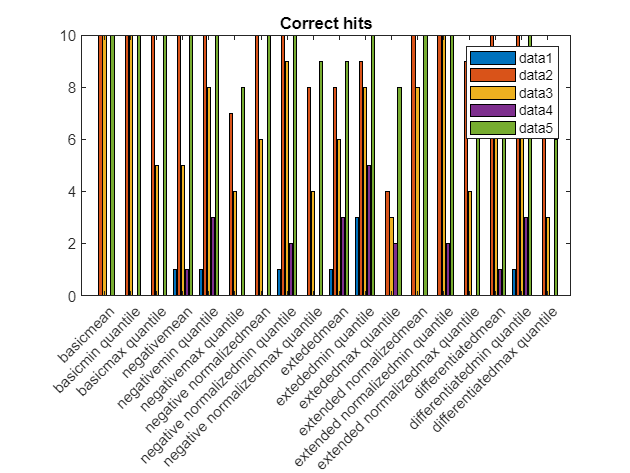

allLabels = [];
for i = 1:length(allApproximations)
    convIdx = floor((i-1) / 3) + 1;
    allLabels = [allLabels, string(convTypes(convIdx).name + allApproximations(i).name)];
end
x = categorical(allLabels);
x = reordercats(x, allLabels);

bar(x, testHitsCorrect)
legend()
title("Correct hits")

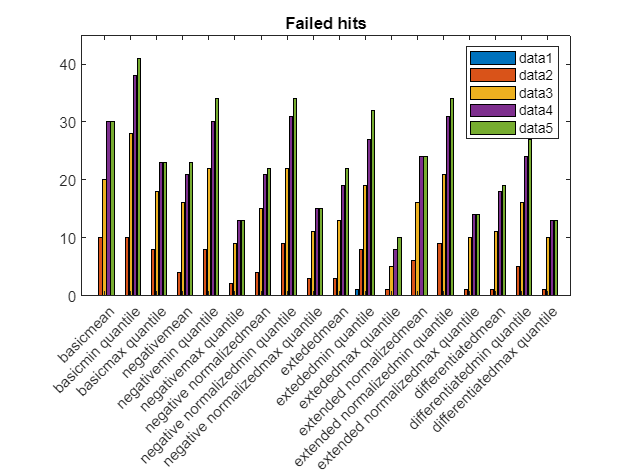


bar(x, testHitsFailed)
legend()
title("Failed hits")

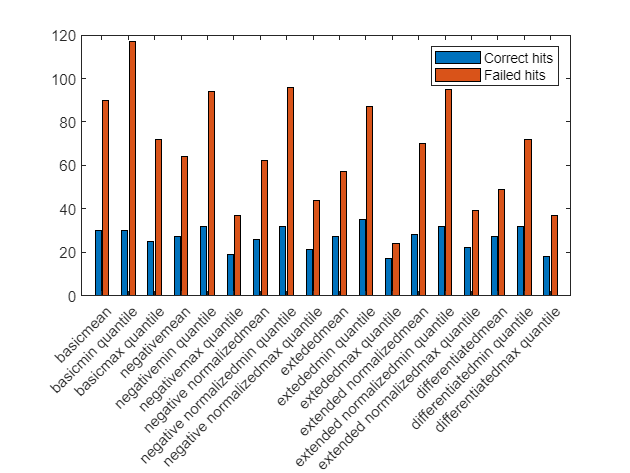


allStats = zeros(2, length(allApproximations));
allStats(1, :) = sum(testHitsCorrect(1:5, :));
allStats(2, :) = sum(testHitsFailed(1:5, :));

allLabels = [];
for i = 1:length(allApproximations)
    convIdx = floor((i-1) / 3) + 1;
    allLabels = [allLabels, string(convTypes(convIdx).name + allApproximations(i).name)];
end
x = categorical(allLabels);
x = reordercats(x, allLabels);

bar(x, transpose(allStats))
legend("Correct hits", "Failed hits")

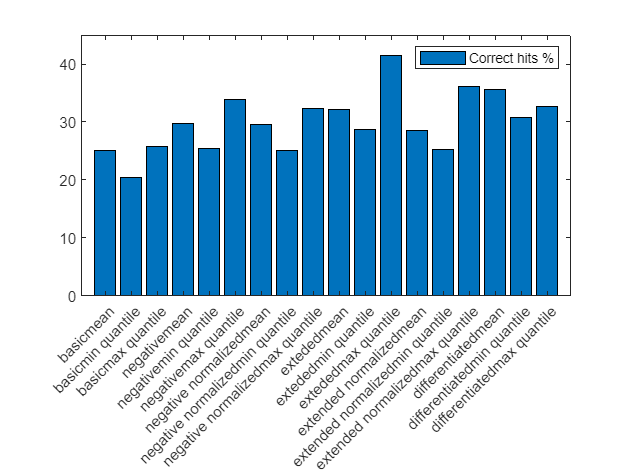

figure
correct_hits_perc = zeros(1, length(allApproximations));
correct_hits_perc(1, :) = allStats(1, :) ./ (allStats(2, :) + allStats(1, :)) .* 100;
bar(x, correct_hits_perc)
legend("Correct hits %")

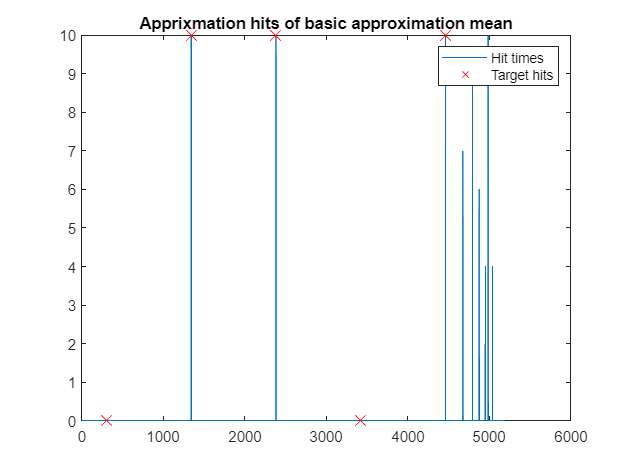

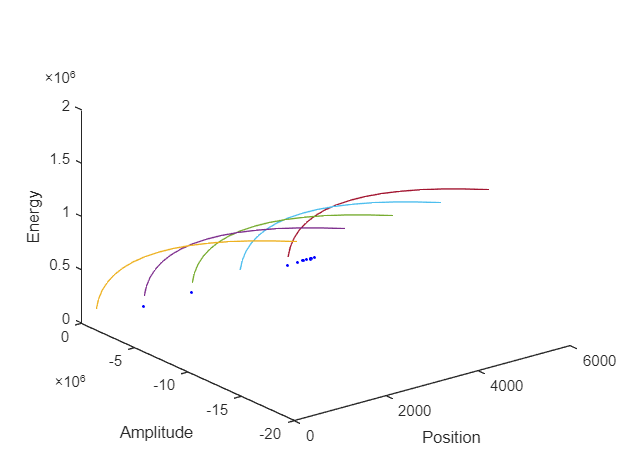

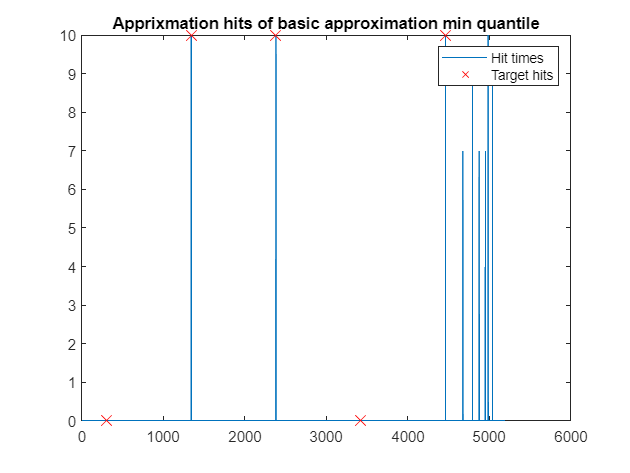

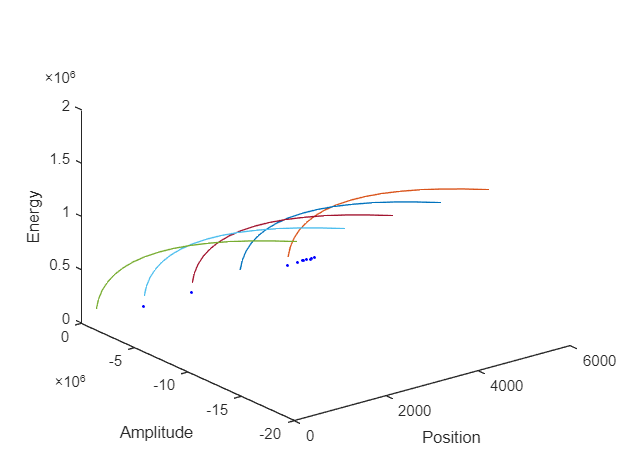

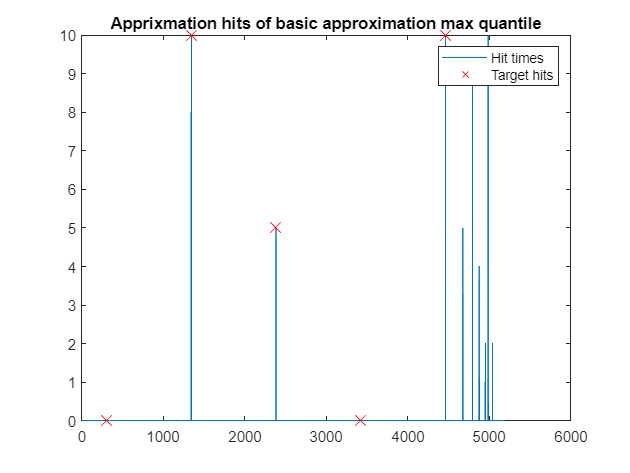

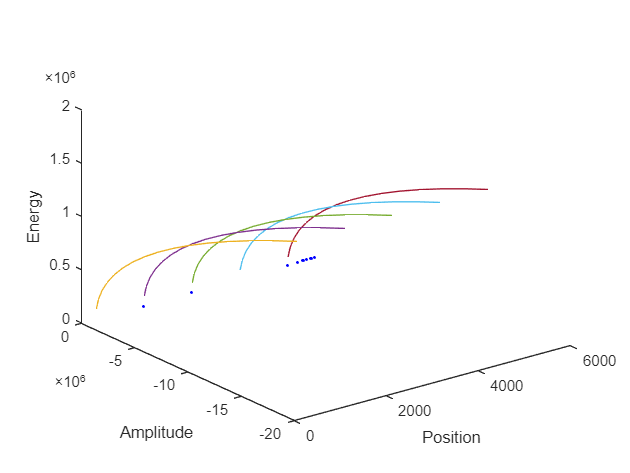

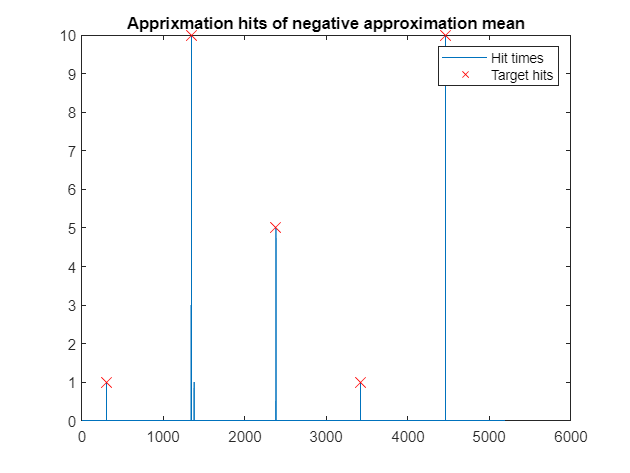

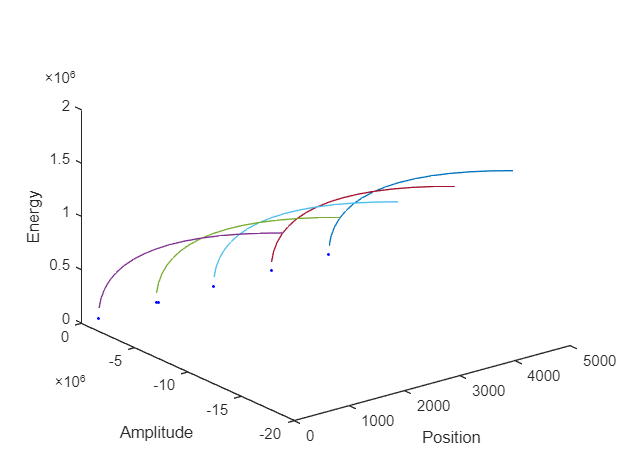

for convIndex = 1:uint32(ConvolutionEnum.last)
    for approxIndex = 1:uint32(ApproximationEnum.last)
        approximationIndex = (convIndex-1) * uint32(ApproximationEnum.last) + approxIndex;
        targetPointsX = zeros(1, stepCount);
        targetPointsY = zeros(1, stepCount);
        for ii = 1:stepCount
            targetPointsX(ii) = convTypes(convIndex).expectedMaximum + singleSigLength * (ii-1);
            targetPointsY(ii) = testAllHits(approximationIndex, targetPointsX(ii));
        end

        figure
        plot(testAllHits(approximationIndex, :), 'DisplayName', "Hit times")
        hold on
        scatter(targetPointsX, targetPointsY,100, 'x','red', 'DisplayName', "Target hits")
        hold off
        title(sprintf("Apprixmation hits of %s approximation %s", convTypes(convIndex).name, allApproximations(approximationIndex).name))
        legend

        figure
        plot3(0, 0, 0)
        hold on
        for i = 1:singleSigLength * stepCount
            for ii = 1:10:testAllHits(approximationIndex, i)
                plot3(i, testAllHitsAmplitude(approximationIndex, i, ii),testAllHitsEnergy(approximationIndex, i, ii), '.',"Color", "b")
            end
        end
        for i = 1:stepCount
            plot_x = zeros(1, 16);
            plot_y = zeros(1, 16);
            plot_z = zeros(1, 16);
            for point = 1:16
                energy = point*100000;
                plot_x(point) = targetPointsX(i);
                plot_z(point) = energy;
                plot_y(point) = energy^2*allApproximations(approximationIndex).coeficients(1)+energy*allApproximations(approximationIndex).coeficients(2)+allApproximations(approximationIndex).coeficients(3);
            end
            plot3(plot_x, plot_y, plot_z)
        end
        
        hold off
        xlabel("Position")
        ylabel("Amplitude")
        zlabel("Energy")
    end
end